%Clear Previous Work
clear all
clc

%Set Directory
cd('ENTER LOCATION HERE')

%Pull in Data
[num,txt,raw] = xlsread('Walk_Test.xlsx');

%Specify Data
measuredTorque = -1 * num(5,:);
perscribedTorque = -1 * num(6,:);
fsr = num(13,:);
state = num(7,:);

clear num raw txt


## Find Start and End of Every Gait Cycle

x = 1;  %Initializes internal idx

%Finding starting point
for i = 2:length(fsr)
    if state(i) > 0 && state(i-1) ==0
        stateIdx(x,1) = i;
        x = x + 1;
    end
end

clear x

%Estimate for Difference Between Toe Strike and Heel Strike for Gait Cycle
startIdx = stateIdx - 8; %Based on Previous Walks

%Finding ending point and length
for i = 2:length(startIdx)

    startIdx(i-1,2) = startIdx(i) - 1;
    startIdx(i-1,3) = startIdx(i-1,2) - startIdx(i-1,1);

end

%Removes last, incomplete step
startIdx(end,:) = [];

%Remove Outlier Steps
meanDiff = mean(startIdx(:,3));
stdDiff = std(startIdx(:,3));

for i = 1:length(startIdx(:,3))
    if startIdx(i,3) >= meanDiff + (4 * stdDiff)
        startIdx(i,:) = 0;
    end
end

startIdx = startIdx(any(startIdx,2),:);

clear i

## Segment Data into Steps

%Sorts into Steps
for i = 1:length(startIdx)

    mTorque{i} = measuredTorque(1,startIdx(i,1):startIdx(i,2));
    pTorque{i} = perscribedTorque(1,startIdx(i,1):startIdx(i,2));

end

clear i

%Remove Empty Steps
idxToRemove = [];

for i = 1:numel(pTorque)
    if all(pTorque{i} == 0)
        idxToRemove = [idxToRemove,i];
    end
end

mTorque(idxToRemove) = [];
pTorque(idxToRemove) = [];

%Remove Low Setpoint Torques
for i = 1:numel(pTorque)
    maxValues(i,1) = max(pTorque{i});
    maxValues(i,2) = min(pTorque{i});
    maxValues(i,3) = maxValues(i,1) - maxValues(i,2);
end

idx(1,1) = 0;

for i = 2:length(maxValues)  
    if maxValues(i,1) >= 25 && maxValues(i-1,1) < 25
        idx(1,1) = i;
    end
end
if idx > 0
    mTorque(1:max(idx)-1) = [];
    pTorque(1:max(idx)-1) = [];
end

## Calculate RMSE

for i = 1:length(mTorque)

    for n = 1:length(pTorque{i})
        error(n) = pTorque{i}(n) - mTorque{i}(n);
        squared_errors(n) = error(n)^2;
        mean_squared_errors(i) = mean(squared_errors);
        rmse(i) = sqrt(mean_squared_errors(i));
    end

    clear error squared_errors

end

RMSE_mean = mean(rmse);


## Find the Average Waveform

%Normalize to Gait Cycle
for i = 1:length(mTorque)
    mesTorque(1:101,i) = resample(mTorque{1,i},101,length(mTorque{1,i}));
    command(1:101,i) = resample(pTorque{1,i},101,length(pTorque{1,i}));
end

% %Remove "Funky" Steps
% [maximumVal,maxIdx] = max(mesTorque);
% [minimumVal,minIdx] = min(mesTorque);
% 
% for i = 1:length(maxIdx)
%     if maxIdx(i) > 35 || minimumVal(i) < -2.5
%         mesTorque(:,i) = 0;
%         command(:,i) = 0;
%     end
% end
% 
% mesTorque = mesTorque(:,~all(mesTorque == 0));
% command = command(:,~all(command == 0));

%Find Average and Standard Deviation for Each 
Averaged_MeasuredTorque = mean(mesTorque,2);
Std_MeasuredTorque = std(mesTorque,0,2);
Averaged_PerscribedTorque = mean(command,2);

maxPrescribed = max(Averaged_PerscribedTorque);

## Calculate Updated RMSE

% for i = 1:length(mesTorque(1,:))
%     for n = 1:length(command)
%         updatederror(n) = command(n,i) - mesTorque(n,i);
%         updated_se(n) = updatederror(n)^2;
%     end
%     updated_mse(i) = mean(updated_se);
%     updatedrmse(i) = sqrt(updated_mse(i));
% end
% updatedRMSE = mean(updatedrmse);


## Plot Data and Save Figure

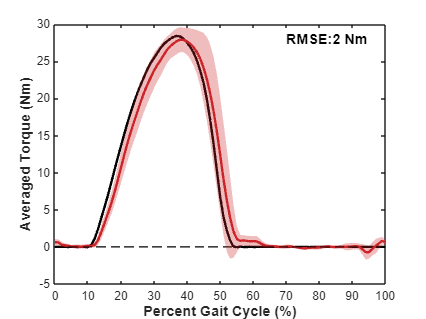

figure;
z(1:101,1) = 0:100;
plot(0:100,Averaged_PerscribedTorque,'k','LineWidth',2);
hold on
plot(0:100,Averaged_MeasuredTorque,'Color',[204 37 41]./255,'LineWidth',2);
hold on
plot(z,zeros(length(z)),'k','LineStyle','--');
hold on
x_fill = [z; flipud(z)];
y_fill = [Averaged_MeasuredTorque + Std_MeasuredTorque; flipud(Averaged_MeasuredTorque - Std_MeasuredTorque)];
fill(x_fill,y_fill,[204 37 41]./255,'FaceAlpha',0.3,'EdgeColor','none');
hold on
text(70,28,strcat('RMSE: ',num2str(round(RMSE_mean,2)),' Nm'),'FontSize',12,'FontWeight','bold');
xlabel('Percent Gait Cycle (%)','FontWeight','bold', 'FontSize',12);
ylabel('Averaged Torque (Nm)','FontWeight','bold','FontSize',12);
xticks(0:10:100);
ylim([-5 30]);

%legend('Perscribed Torque','Measured Torque','FontWeight','bold','FontSize',12,'Location','best');

%saveas(gcf,'Ankle_Torque_Profile_Final','svg')